Mex_dash=readtimetable('220227COVID19MEXICO.csv');

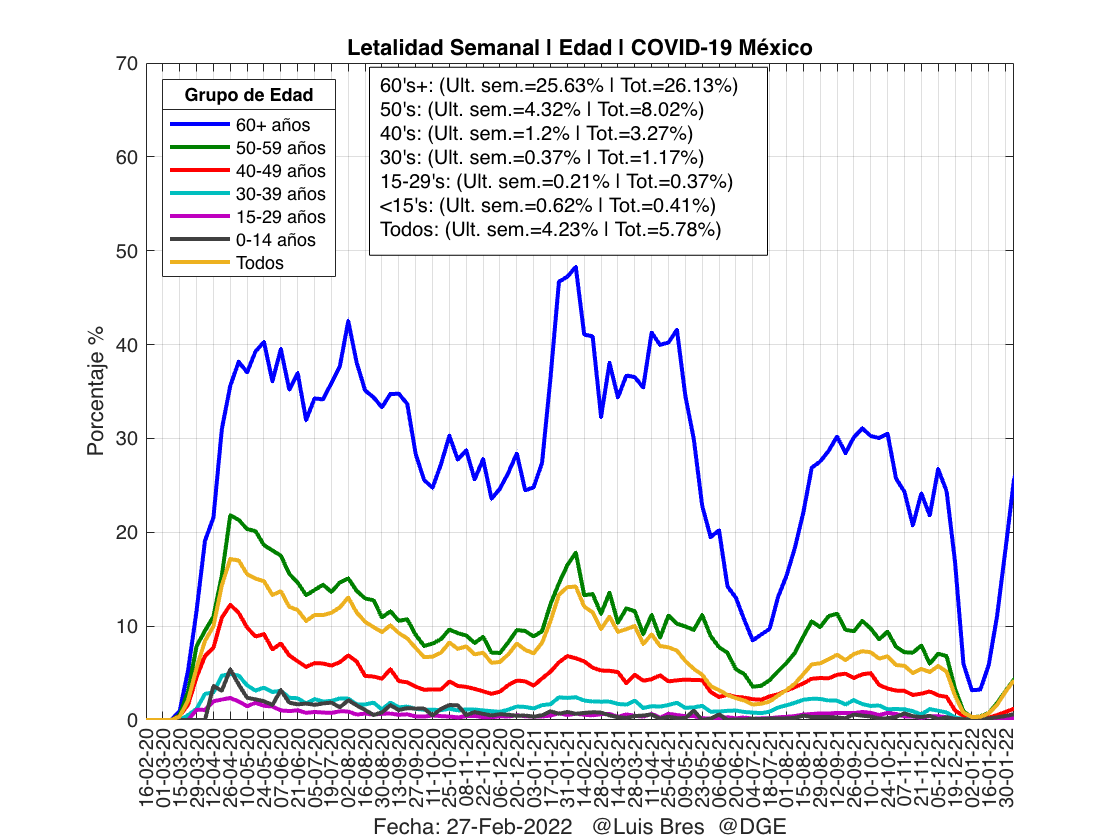

% Letalidad
figure
[pl60,l60,abs60]=letalidad(60,150,1,Mex_dash);
hold on
[pl50,l50,abs50]=letalidad(50,59,1,Mex_dash);
[pl40,l40,abs40]=letalidad(40,49,1,Mex_dash);
[pl30,l30,abs30]=letalidad(30,39,1,Mex_dash);
[pl18,l18,abs18]=letalidad(15,29,1,Mex_dash);
[pl00,l00,abs00]=letalidad(0,14,1,Mex_dash);
[plall,lall,absall]=letalidad(0,150,2,Mex_dash);
leta=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años','Todos'},'Location','NorthWest');
title(leta,'Grupo de Edad')
grid()
ylim([0 70])
hold off
L60=string(round(l60(end-2),2));
L50=string(round(l50(end-2),2));
L40=string(round(l40(end-2),2));
L30=string(round(l30(end-2),2));
L18=string(round(l18(end-2),2));
L00=string(round(l00(end-2),2));
Lall=string(round(lall(end-2),2));

La60=string(round(abs60,2));
La50=string(round(abs50,2));
La40=string(round(abs40,2));
La30=string(round(abs30,2));
La18=string(round(abs18,2));
La00=string(round(abs00,2));
Laall=string(round(absall,2));
dim = [.33, .92, 0.0, 0.0];
str = {"60's+: (Ult. sem.="+L60+"%"+" | Tot.="+La60+"%)",...
       "50's: (Ult. sem.="+L50+"%"+" | Tot.="+La50+"%)",...
       "40's: (Ult. sem.="+L40+"%"+" | Tot.="+La40+"%)",...
       "30's: (Ult. sem.="+L30+"%"+" | Tot.="+La30+"%)",...
       "15-29's: (Ult. sem.="+L18+"%"+" | Tot.="+La18+"%)",...
       "<15's: (Ult. sem.="+L00+"%"+" | Tot.="+La00+"%)",...
       "Todos: (Ult. sem.="+Lall+"%"+" | Tot.="+Laall+"%)"
       };
textbox=annotation('textbox',dim,'String',str,'FitBoxToText','on');
set(textbox,'BackgroundColor','white')

str1 = ["60's+: Ult. sem.="+L60+"%"+" | Tot.="+La60+"%";...
       "50's: Ult. sem.="+L50+"%"+" | Tot.="+La50+"%";...
       "40's: Ult. sem.="+L40+"%"+" | Tot.="+La40+"%";...
       "30's: Ult. sem.="+L30+"%"+" | Tot.="+La30+"%";...
       "15-29's: Ult. sem.="+L18+"%"+" | Tot.="+La18+"%";...
       "<15's: Ult. sem.="+L00+"%"+" | Tot.="+La00+"%";...
       "Todos: Ult. sem.="+Lall+"%"+" | Tot.="+Laall+"%";
       ];
disp(str1)

    "60's+: Ult. sem.=25.63% | Tot.=26.13%"
    "50's: Ult. sem.=4.32% | Tot.=8.02%"
    "40's: Ult. sem.=1.2% | Tot.=3.27%"
    "30's: Ult. sem.=0.37% | Tot.=1.17%"
    "15-29's: Ult. sem.=0.21% | Tot.=0.37%"
    "<15's: Ult. sem.=0.62% | Tot.=0.41%"
    "Todos: Ult. sem.=4.23% | Tot.=5.78%"



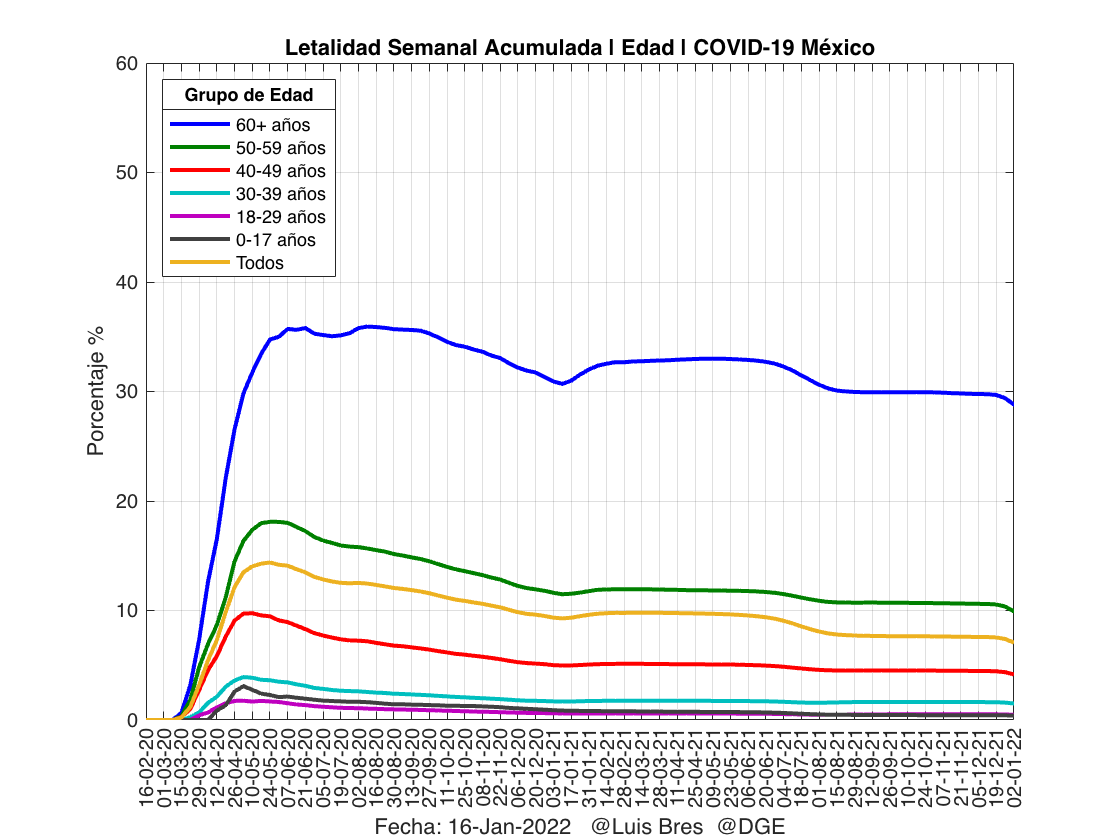

% Letalidad acumulada
figure
[pl60s,l60s,abs60s]=letalidad_sum(60,150,1,Mex_dash);
hold on
[pl50s,l50s,abs50s]=letalidad_sum(50,59,1,Mex_dash);
[pl40s,l40s,abs40s]=letalidad_sum(40,49,1,Mex_dash);
[pl30s,l30s,abs30s]=letalidad_sum(30,39,1,Mex_dash);
[pl18s,l18s,abs18s]=letalidad_sum(15,29,1,Mex_dash);
[pl00s,l00s,abs00s]=letalidad_sum(0,14,1,Mex_dash);
[plalls,lalls,absalls]=letalidad_sum(0,150,2,Mex_dash);
letas=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años','Todos'},'Location','NorthWest');
title(letas,'Grupo de Edad')
grid()
ylim([0 60])
hold off

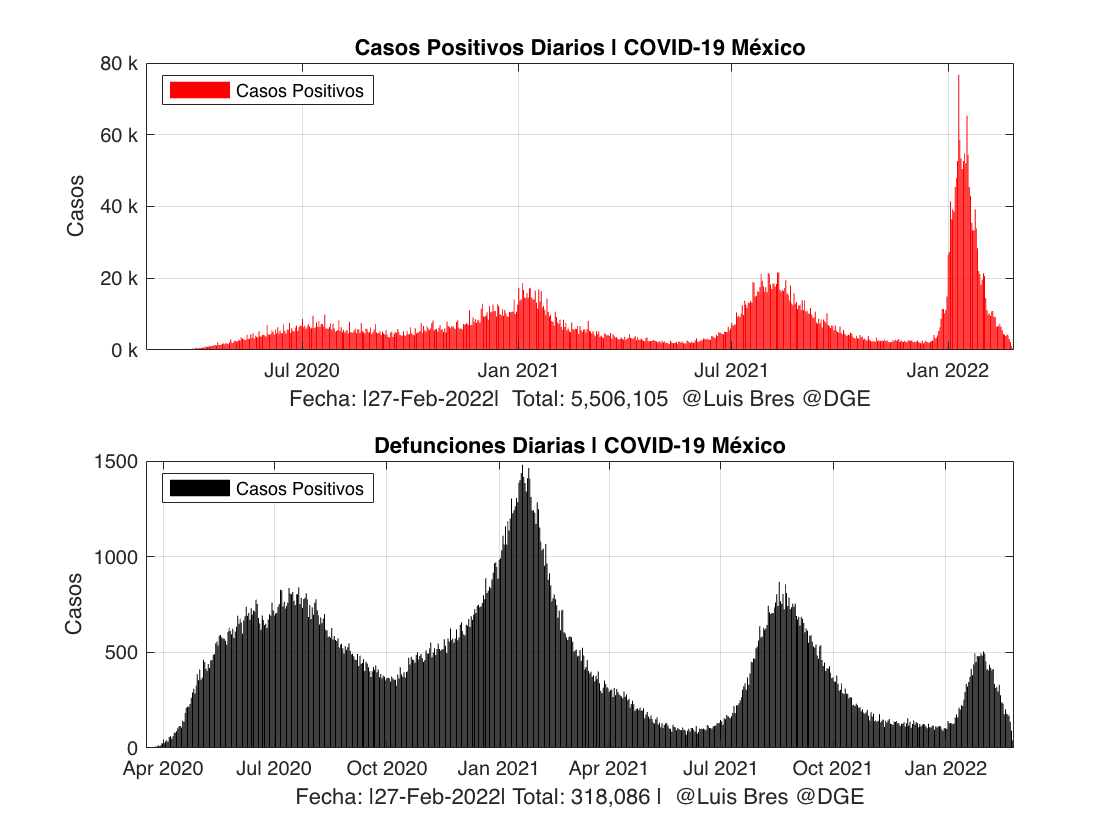

% Casos diarios
figure
subplot(2,1,1)
[tdp,casos,p]=Mex_casos_dia(Mex_dash); 
subplot(2,1,2)
[m,tdm,muertes]=Mex_muertes_dia(Mex_dash);

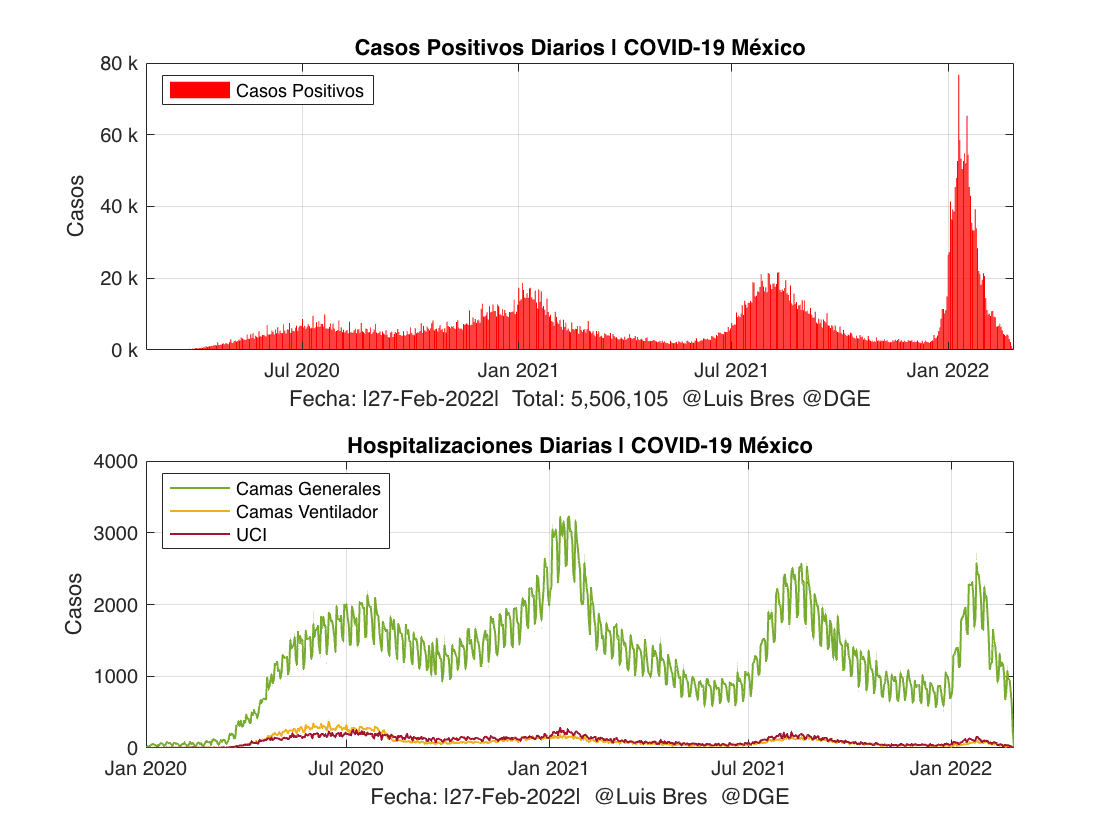

%Hospitalizaciones
figure
subplot(2,1,1)
Mex_casos_dia(Mex_dash);
subplot(2,1,2)
[h,tdh1,hosp,hospg1,hospv1,hospuci1]=Mex_hosp_dia(Mex_dash);

% Empalme de casos/muertes
TTc =timetable(tdp,casos);
Wc=retime(TTc,"weekly","sum");

tc = Wc.Properties.RowTimes;
CASOS = Wc.casos;


TTm =timetable(tdm,muertes);
Wm=retime(TTm,"weekly","sum");
Csem=2;
tm = Wm.Properties.RowTimes;
MUERTES=Wm.muertes;
figure
colororder({'k','k'})
yyaxis left
plot(tc(1:1:(length(tc)-Csem)),1e-3*CASOS(1:1:(length(CASOS)-Csem)),'b','LineWidth',2)
ylim([0 410])
ytickformat('%g k ')
ylabel('# Casos Positivos')
hold on
yyaxis right
plot(tm(1:1:(length(tm)-Csem+1)),1e-3*MUERTES(1:1:(length(MUERTES)-Csem+1)),'k','LineWidth',2)
ylim([0 40])
ytickformat('%g k ')
ylabel('# Defunciones')
hold off
grid()
ts_Mex_dash = tc(1);
tf_Mex_dash =tc(length(tc)-Csem);
xlim([ts_Mex_dash tf_Mex_dash])
date1=datestr(tc(length(tc)-Csem),'dd/mm/yy');
date2=datestr(tc(length(tc)-Csem-1),'dd/mm/yy');
title('Casos Positivos/Defunciones Semanales | COVID-19 México')
xtickformat('MMM-yyyy')
cc=CASOS((length(CASOS)-Csem-1));
cc2=CASOS((length(CASOS)-Csem));
mm=MUERTES((length(MUERTES)-Csem));
mm2=MUERTES((length(MUERTES)-Csem+1));
Cchange=(-cc+cc2)/cc*100;
Mchange=(mm2-mm)/mm*100;
casos_change=string(round(Cchange,2));
muertes_change=string(round(Mchange,2));
dimcasos= [.13, .805, 0.0, 0.0];
strcasos = {"% de cambio del "+date1+" al "+date2+":",...
    "Casos positivos: "+casos_change+"%",...
    "Muertes: "+muertes_change+"%"
       };
strcasos1 = ["% de cambio del "+date1+" al "+date2+":";...
    "Casos positivos: "+casos_change+"%";...
    "Muertes: "+muertes_change+"%"
       ];
disp(strcasos1)

    "% de cambio del 06/02/22 al 30/01/22:"
    "Casos positivos: -41.66%"
    "Muertes: -33.7%"



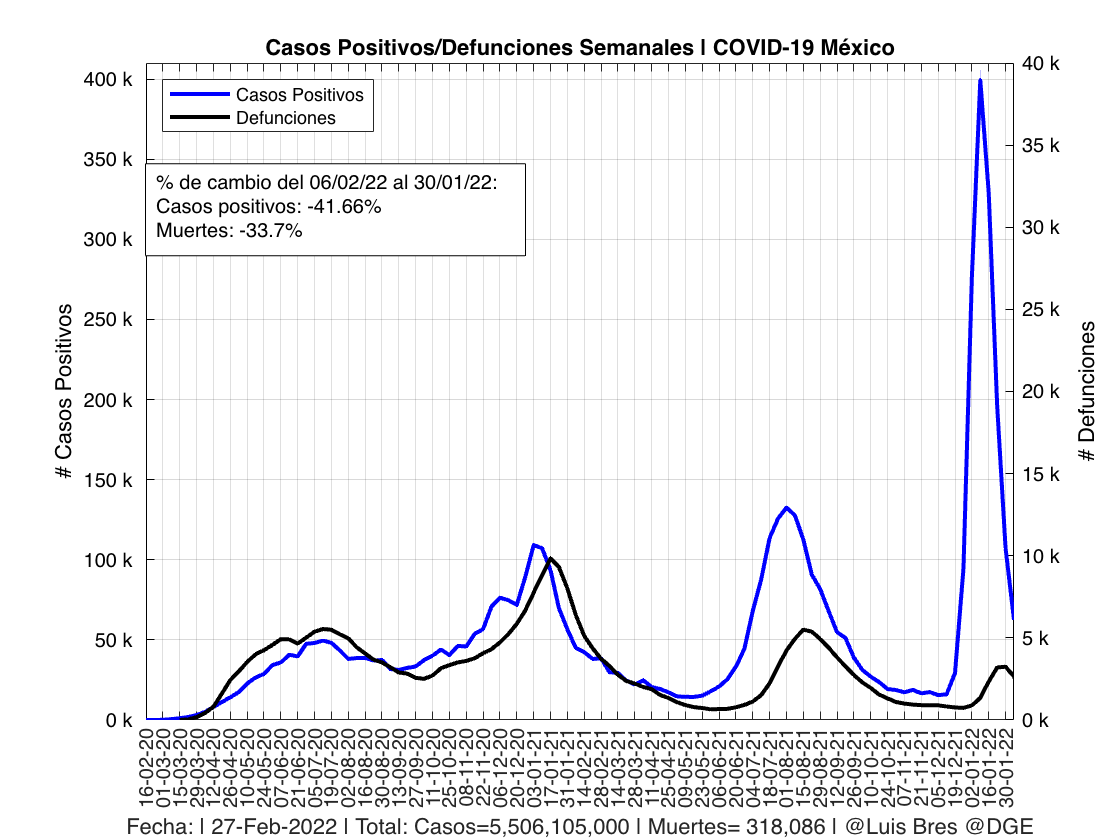

textboxcasos=annotation('textbox',dimcasos,'String',strcasos,'FitBoxToText','on');
set(textboxcasos,'BackgroundColor','white')
Ce=CommaFormat(sum(CASOS)*1e3);
Me=CommaFormat(sum(MUERTES));
xlabel("Fecha: | "+date+" | "+"Total: Casos="+Ce+" | Muertes= "+Me+" | @Luis Bres @DGE")
legend({'Casos Positivos','Defunciones'},"Location","northwest")
xticks(tc(1:2:length(tc)))
xtickangle(90)
xtickformat('dd-MM-yy')

% Empalme casos/hospitalizaciones
TTh =timetable(tdh1,hospg1,hospv1,hospuci1);
Wh=retime(TTh,"weekly","sum");

tdh = Wh.Properties.RowTimes;
hospg=Wh.hospg1;
hospv=Wh.hospv1;
hospuci=Wh.hospuci1;
figure
colororder({'k','k'})
yyaxis left
plot(tc(1:1:(length(tc)-2)),1e-3*CASOS(1:1:(length(CASOS)-2)),'b','LineWidth',2)
ylim([0 410])
ytickformat('%g k ')
ylabel('# Casos Positivos')
hold on
yyaxis right
H=plot(tdh(1:1:(length(tdh)-Csem)),hospg(1:1:(length(hospg)-Csem))*1e-3,'-',...
    tdh(1:1:(length(tdh)-Csem)),hospv(1:1:(length(hospv)-Csem))*0.5e-2,'-',...
    tdh(1:1:(length(tdh)-Csem)),hospuci(1:1:(length(hospuci)-Csem))*0.5e-2,'-');
H(1).Color=[0.4660 0.6740 0.1880];   
H(1).LineWidth = 2; 
H(2).Color=[0.9290 0.6940 0.1250];
H(2).LineWidth = 1; 
H(3).Color=[0.6350 0.0780 0.1840];
H(3).LineWidth = 1; 
ylim([0 90])
ytickformat('%g k ')
ylabel('# Admisiones Hospitalarias')
hold off
grid()
ts_Mex_dash = tc(1);
tf_Mex_dash =tc(length(tc)-Csem);
xlim([ts_Mex_dash tf_Mex_dash])
title('Casos Positivos/Hospitalizaciones Diarias | COVID-19 México')
xtickformat('MMM-yyyy')


cc=CASOS((length(CASOS)-Csem-1));
cc2=CASOS((length(CASOS)-Csem));
Cchange=(-cc+cc2)/cc*100;
casos_change=string(round(Cchange,2));

hg=hospg((length(hospg)-Csem-1));
hg2=hospg((length(hospg)-Csem));
HGchange=(hg2-hg)/mm*100;
hg_change=string(round(HGchange,2));

hv=hospv((length(hospv)-Csem-1));
hv2=hospv((length(hospv)-Csem));
HVchange=(hv2-hv)/mm*100;
hv_change=string(round(HVchange,2));

hu=hospuci((length(hospuci)-Csem-1));
hu2=hospuci((length(hospuci)-Csem));
HUchange=(hu2-hu)/mm*100;
hu_change=string(round(HUchange,2));


dimcasos= [.13, .77, 0, 0.0];
strhosps = {"% de cambio del "+date1+" al "+date2+":",...
    "Casos positivos: "+casos_change+"%",...
    "Hosps. General: "+hg_change+"%",...
    "Hosps. Ventilador: "+hv_change+"%",...
    "Hosps. UCI: "+hu_change+"%"
       };
strhosps1 = ["% de cambio del "+date1+" al "+date2+":";...
    "Hosps. General: "+hg_change+"%";...
    "Hosps. Ventilador: "+hv_change+"%";...
    "Hosps. UCI: "+hu_change+"%"
       ];
disp(strhosps1)

    "% de cambio del 06/02/22 al 30/01/22:"
    "Hosps. General: -59.3%"
    "Hosps. Ventilador: -4.8%"
    "Hosps. UCI: -6.77%"



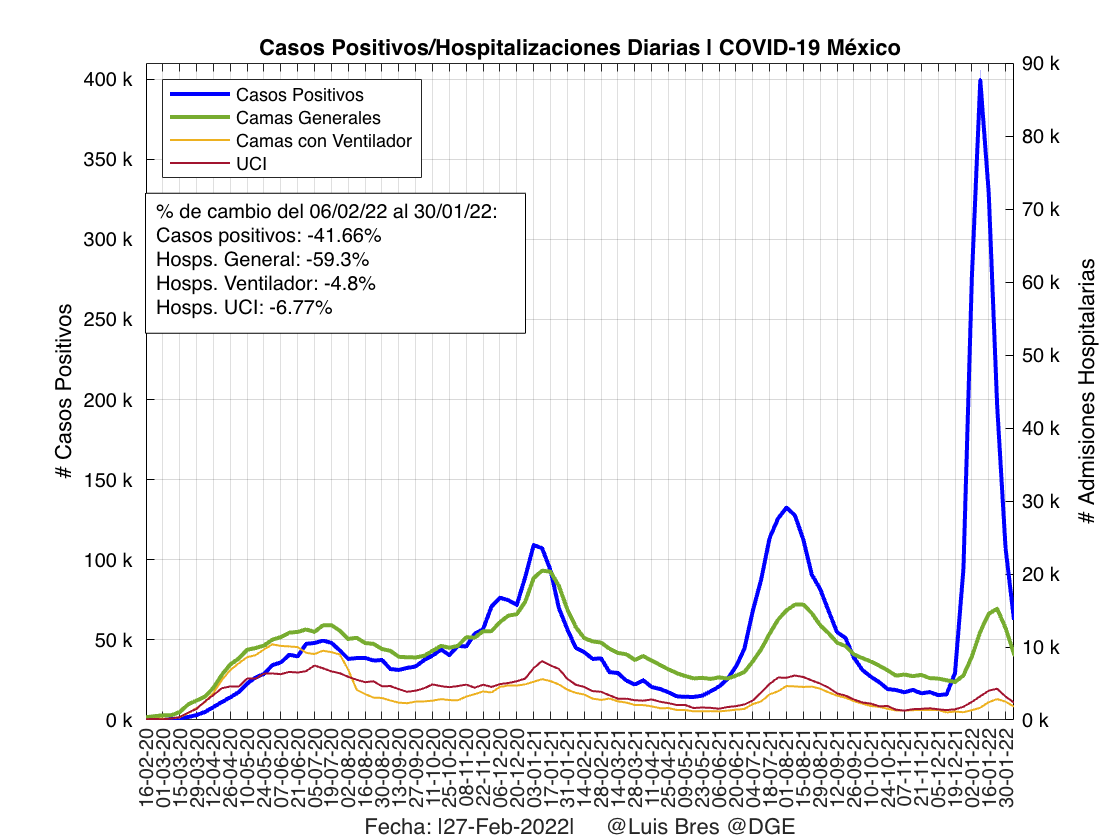

textboxhosps=annotation('textbox',dimcasos,'String',strhosps,'FitBoxToText','on');
set(textboxhosps,'BackgroundColor','white')

xlabel("Fecha: |"+date+"|"+"     @Luis Bres @DGE")
legend({'Casos Positivos','Camas Generales','Camas con Ventilador','UCI'},"Location","northwest")
xticks(tc(1:2:length(tc)))
xtickangle(90)
xtickformat('dd-MM-yy')

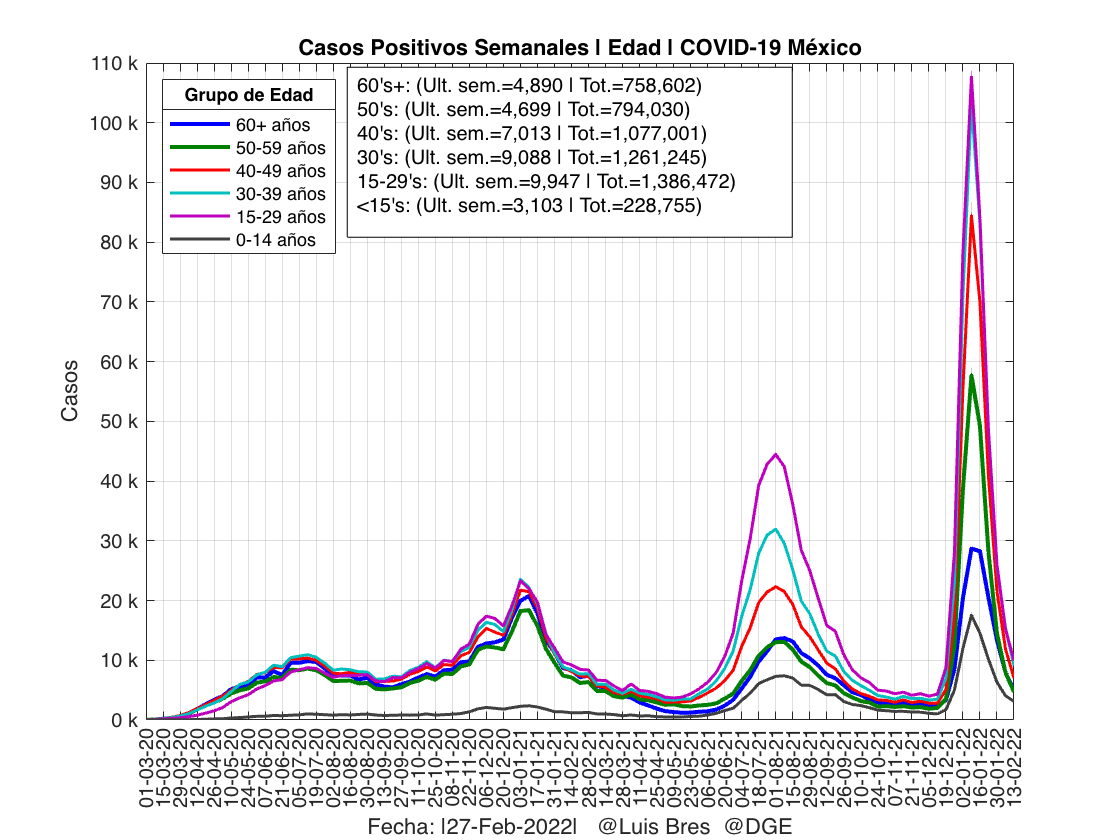

% Casos edad
figure
qc=1;
[c60,cs60,pc60]=Mex_casos_edad(Mex_dash,60,150,qc);
hold on
[c50,cs50,pc50]=Mex_casos_edad(Mex_dash,50,59,qc);
[c40,cs40,pc40]=Mex_casos_edad(Mex_dash,40,49,qc);
[c30,cs30,pc30]=Mex_casos_edad(Mex_dash,30,39,qc);
[c18,cs18,pc18]=Mex_casos_edad(Mex_dash,15,29,qc);
[c00,cs00,pc00]=Mex_casos_edad(Mex_dash,0,14,qc);
grid()
ylim([0 110])
lc=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años'},'Location','NorthWest');
title(lc,'Grupo de Edad')
hold off
C60=CommaFormat(round(c60(end-qc),2));
C50=CommaFormat(round(c50(end-qc),2));
C40=CommaFormat(round(c40(end-qc),2));
C30=CommaFormat(round(c30(end-qc),2));
C18=CommaFormat(round(c18(end-qc),2));
C00=CommaFormat(round(c00(end-qc),2));

Ca60=CommaFormat(round(cs60,2));
Ca50=CommaFormat(round(cs50,2));
Ca40=CommaFormat(round(cs40,2));
Ca30=CommaFormat(round(cs30,2));
Ca18=CommaFormat(round(cs18,2));
Ca00=CommaFormat(round(cs00,2));

dimc = [.31, .92, 0.0, 0.0];
strc = {"60's+: (Ult. sem.="+C60+" | Tot.="+Ca60+")",...
       "50's: (Ult. sem.="+C50+" | Tot.="+Ca50+")",...
       "40's: (Ult. sem.="+C40+" | Tot.="+Ca40+")",...
       "30's: (Ult. sem.="+C30+" | Tot.="+Ca30+")",...
       "15-29's: (Ult. sem.="+C18+" | Tot.="+Ca18+")",...
       "<15's: (Ult. sem.="+C00+" | Tot.="+Ca00+")"
       };
textboxc=annotation('textbox',dimc,'String',strc,'FitBoxToText','on');
set(textboxc,'BackgroundColor','white')

strc1 = ["60's+: Ult. sem.="+C60+" | Tot.="+Ca60;...
       "50's: Ult. sem.="+C50+" | Tot.="+Ca50;...
       "40's: Ult. sem.="+C40+" | Tot.="+Ca40;...
       "30's: Ult. sem.="+C30+" | Tot.="+Ca30;...
       "15-29's: Ult. sem.="+C18+" | Tot.="+Ca18;...
       "<15's: Ult. sem.="+C00+" | Tot.="+Ca00;
       ];
disp(strc1)

    "60's+: Ult. sem.=4,890 | Tot.=758,602"
    "50's: Ult. sem.=4,699 | Tot.=794,030"
    "40's: Ult. sem.=7,013 | Tot.=1,077,001"
    "30's: Ult. sem.=9,088 | Tot.=1,261,245"
    "15-29's: Ult. sem.=9,947 | Tot.=1,386,472"
    "<15's: Ult. sem.=3,103 | Tot.=228,755"



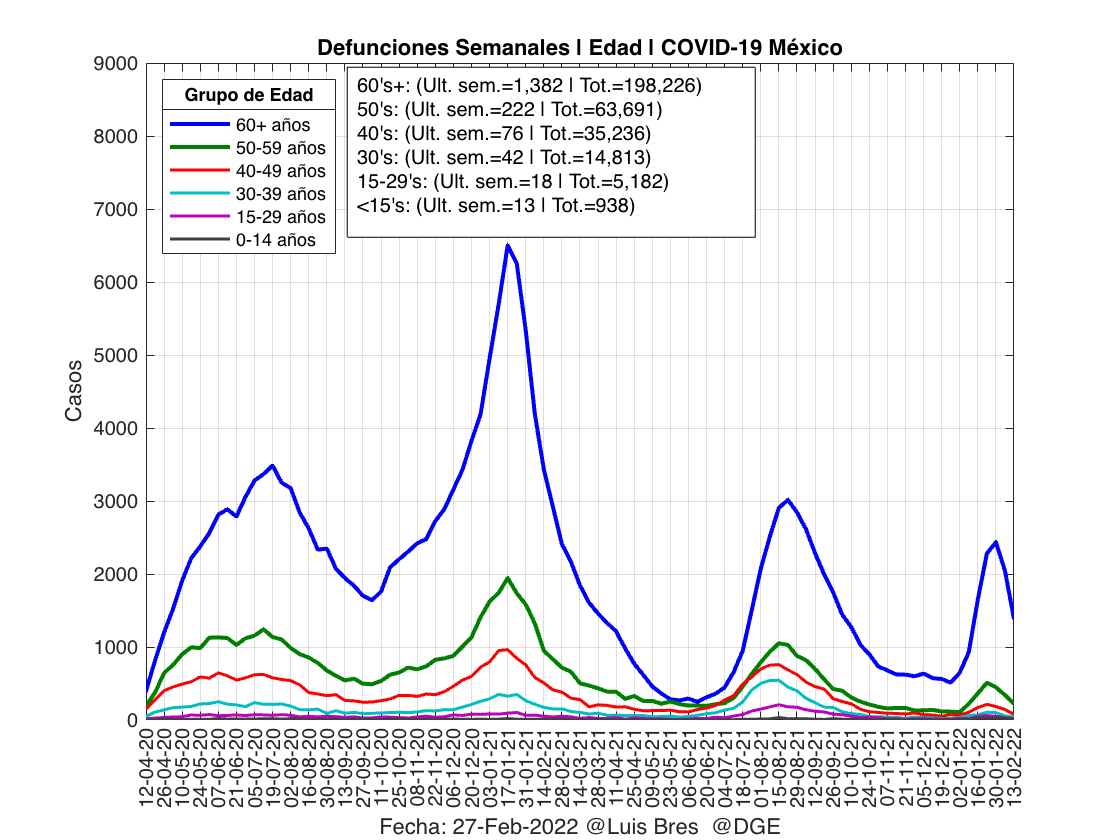

% Muertes edad
figure
qm=1;
[m60,ms60,pm60]=Mex_muertes_edad(Mex_dash,60,150,qm);
hold on
[m50,ms50,pm50]=Mex_muertes_edad(Mex_dash,50,59,qm);
[m40,ms40,pm40]=Mex_muertes_edad(Mex_dash,40,49,qm);
[m30,ms30,pm30]=Mex_muertes_edad(Mex_dash,30,39,qm);
[m18,ms18,pm18]=Mex_muertes_edad(Mex_dash,15,29,qm);
[m00,ms00,pm00]=Mex_muertes_edad(Mex_dash,0,14,qm);
grid()
lm=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años'},'Location','NorthWest');
title(lm,'Grupo de Edad')
hold off
M60=CommaFormat(round(m60(end-qm),2));
M50=CommaFormat(round(m50(end-qm),2));
M40=CommaFormat(round(m40(end-qm),2));
M30=CommaFormat(round(m30(end-qm),2));
M18=CommaFormat(round(m18(end-qm),2));
M00=CommaFormat(round(m00(end-qm),2));

Ma60=CommaFormat(round(ms60,2));
Ma50=CommaFormat(round(ms50,2));
Ma40=CommaFormat(round(ms40,2));
Ma30=CommaFormat(round(ms30,2));
Ma18=CommaFormat(round(ms18,2));
Ma00=CommaFormat(round(ms00,2));
ylim([0 9000])
dimm = [.31, .92, 0.0, 0.0];
strm = {"60's+: (Ult. sem.="+M60+" | Tot.="+Ma60+")",...
       "50's: (Ult. sem.="+M50+" | Tot.="+Ma50+")",...
       "40's: (Ult. sem.="+M40+" | Tot.="+Ma40+")",...
       "30's: (Ult. sem.="+M30+" | Tot.="+Ma30+")",...
       "15-29's: (Ult. sem.="+M18+" | Tot.="+Ma18+")",...
       "<15's: (Ult. sem.="+M00+" | Tot.="+Ma00+")"
       };
textboxm=annotation('textbox',dimm,'String',strm,'FitBoxToText','on');
set(textboxm,'BackgroundColor','white')

strm1 = ["60's+: Ult. sem.="+M60+" | Tot.="+Ma60;...
       "50's: Ult. sem.="+M50+" | Tot.="+Ma50;...
       "40's: Ult. sem.="+M40+" | Tot.="+Ma40;...
       "30's: Ult. sem.="+M30+" | Tot.="+Ma30;...
       "15-29's: Ult. sem.="+M18+" | Tot.="+Ma18;...
       "<15's: Ult. sem.="+M00+" | Tot.="+Ma00;
       ];
disp(strm1)

    "60's+: Ult. sem.=1,382 | Tot.=198,226"
    "50's: Ult. sem.=222 | Tot.=63,691"
    "40's: Ult. sem.=76 | Tot.=35,236"
    "30's: Ult. sem.=42 | Tot.=14,813"
    "15-29's: Ult. sem.=18 | Tot.=5,182"
    "<15's: Ult. sem.=13 | Tot.=938"



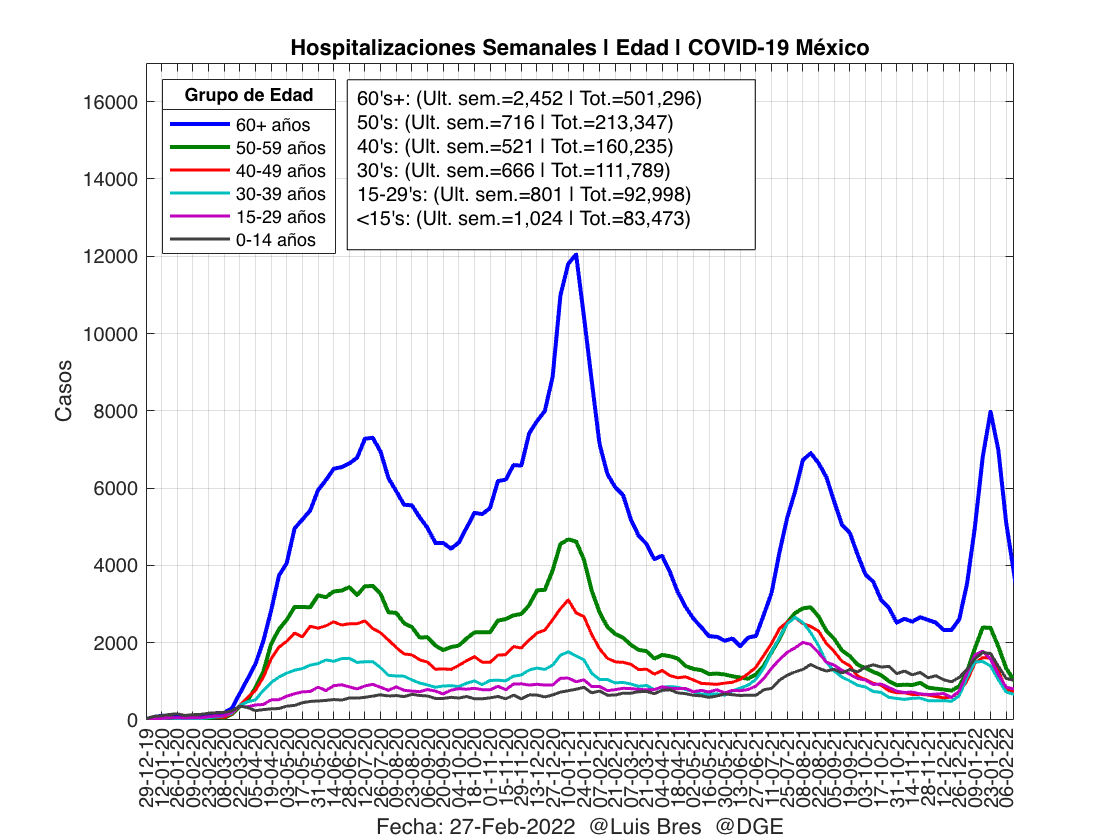

% Hosp edad
figure
H=1;
[h60,hs60,ph60]=Mex_hosp_edad(Mex_dash,60,150,H);
hold on
[h50,hs50,ph50]=Mex_hosp_edad(Mex_dash,50,59,H);
[h40,hs40,ph40]=Mex_hosp_edad(Mex_dash,40,49,H);
[h30,hs30,ph30]=Mex_hosp_edad(Mex_dash,30,39,H);
[h18,hs18,ph18]=Mex_hosp_edad(Mex_dash,15,29,H);
[h00,hs00,ph00]=Mex_hosp_edad(Mex_dash,0,14,H);
lh=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años'},'Location','NorthWest');
title(lh,'Grupo de Edad')
hold off
grid()

H60=CommaFormat(round(h60(end-H),2));
H50=CommaFormat(round(h50(end-H),2));
H40=CommaFormat(round(h40(end-H),2));
H30=CommaFormat(round(h30(end-H),2));
H18=CommaFormat(round(h18(end-H),2));
H00=CommaFormat(round(h00(end-H),2));

Ha60=CommaFormat(round(hs60,2));
Ha50=CommaFormat(round(hs50,2));
Ha40=CommaFormat(round(hs40,2));
Ha30=CommaFormat(round(hs30,2));
Ha18=CommaFormat(round(hs18,2));
Ha00=CommaFormat(round(hs00,2));
ylim([0 17000])
dimh = [.31, .905, 0.0, 0.0];
strh = {"60's+: (Ult. sem.="+H60+" | Tot.="+Ha60+")",...
       "50's: (Ult. sem.="+H50+" | Tot.="+Ha50+")",...
       "40's: (Ult. sem.="+H40+" | Tot.="+Ha40+")",...
       "30's: (Ult. sem.="+H30+" | Tot.="+Ha30+")",...
       "15-29's: (Ult. sem.="+H18+" | Tot.="+Ha18+")",...
       "<15's: (Ult. sem.="+H00+" | Tot.="+Ha00+")"
       };
textboxh=annotation('textbox',dimh,'String',strh,'FitBoxToText','on');
set(textboxh,'BackgroundColor','white')

strh1 = ["60's+: Ult. sem.="+H60+" | Tot.="+Ha60;...
       "50's: Ult. sem.="+H50+" | Tot.="+Ha50;...
       "40's: Ult. sem.="+H40+" | Tot.="+Ha40;...
       "30's: Ult. sem.="+H30+" | Tot.="+Ha30;...
       "15-29's: Ult. sem.="+H18+" | Tot.="+Ha18;...
       "<15's: Ult. sem.="+H00+" | Tot.="+Ha00;
       ];
disp(strh1)

    "60's+: Ult. sem.=2,452 | Tot.=501,296"
    "50's: Ult. sem.=716 | Tot.=213,347"
    "40's: Ult. sem.=521 | Tot.=160,235"
    "30's: Ult. sem.=666 | Tot.=111,789"
    "15-29's: Ult. sem.=801 | Tot.=92,998"
    "<15's: Ult. sem.=1,024 | Tot.=83,473"



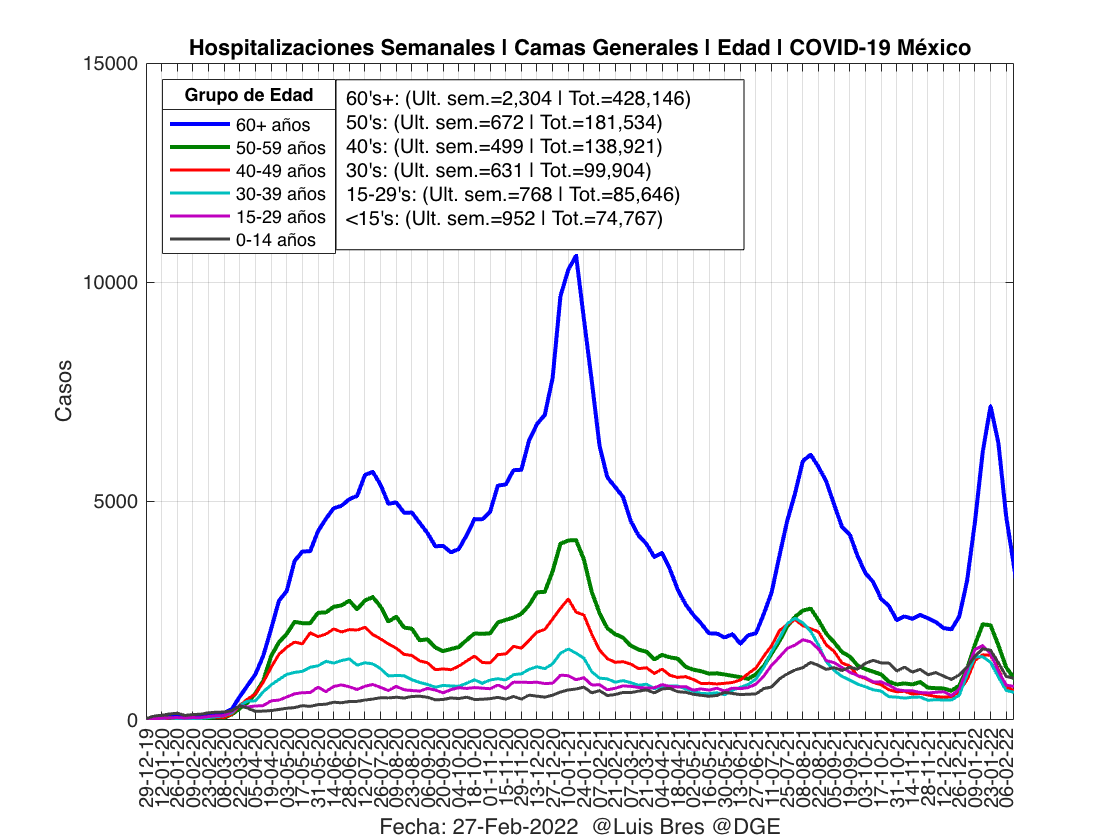

% Hosp edad Generales
figure
G=1;
[hg60,hgs60,phg60]=Mex_hospG_edad(Mex_dash,60,150,G);
hold on
[hg50,hgs50,phg50]=Mex_hospG_edad(Mex_dash,50,59,G);
[hg40,hgs40,phg40]=Mex_hospG_edad(Mex_dash,40,49,G);
[hg30,hgs30,phg30]=Mex_hospG_edad(Mex_dash,30,39,G);
[hg18,hgs18,phg18]=Mex_hospG_edad(Mex_dash,15,29,G);
[hg00,hgs00,phg00]=Mex_hospG_edad(Mex_dash,0,14,G);
lh=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años'},'Location','NorthWest');
title(lh,'Grupo de Edad')
hold off
grid()
Hg60=CommaFormat(round(hg60(end-G),2));
Hg50=CommaFormat(round(hg50(end-G),2));
Hg40=CommaFormat(round(hg40(end-G),2));
Hg30=CommaFormat(round(hg30(end-G),2));
Hg18=CommaFormat(round(hg18(end-G),2));
Hg00=CommaFormat(round(hg00(end-G),2));

Hga60=CommaFormat(round(hgs60,2));
Hga50=CommaFormat(round(hgs50,2));
Hga40=CommaFormat(round(hgs40,2));
Hga30=CommaFormat(round(hgs30,2));
Hga18=CommaFormat(round(hgs18,2));
Hga00=CommaFormat(round(hgs00,2));
ylim([0 15000])
dimhg = [.30, .905, 0.0, 0.0];
strhg = {"60's+: (Ult. sem.="+Hg60+" | Tot.="+Hga60+")",...
       "50's: (Ult. sem.="+Hg50+" | Tot.="+Hga50+")",...
       "40's: (Ult. sem.="+Hg40+" | Tot.="+Hga40+")",...
       "30's: (Ult. sem.="+Hg30+" | Tot.="+Hga30+")",...
       "15-29's: (Ult. sem.="+Hg18+" | Tot.="+Hga18+")",...
       "<15's: (Ult. sem.="+Hg00+" | Tot.="+Hga00+")"
       };
textboxhg=annotation('textbox',dimhg,'String',strhg,'FitBoxToText','on');
set(textboxhg,'BackgroundColor','white')

strhg1 = ["60's+: Ult. sem.="+Hg60+" | Tot.="+Hga60;...
       "50's: Ult. sem.="+Hg50+" | Tot.="+Hga50;...
       "40's: Ult. sem.="+Hg40+" | Tot.="+Hga40;...
       "30's: Ult. sem.="+Hg30+" | Tot.="+Hga30;...
       "18's: Ult. sem.="+Hg18+" | Tot.="+Hga18;...
       "<18's: Ult. sem.="+Hg00+" | Tot.="+Hga00;
       ];
disp(strhg1)

    "60's+: Ult. sem.=2,089 | Tot.=378,087"
    "50's: Ult. sem.=790 | Tot.=165,624"
    "40's: Ult. sem.=521 | Tot.=127,386"
    "30's: Ult. sem.=422 | Tot.=89,220"
    "18's: Ult. sem.=409 | Tot.=64,132"
    "<18's: Ult. sem.=1,097 | Tot.=67,909"



M_H_G=readtable('Sistema de Información de la Red IRAG.xlsx');

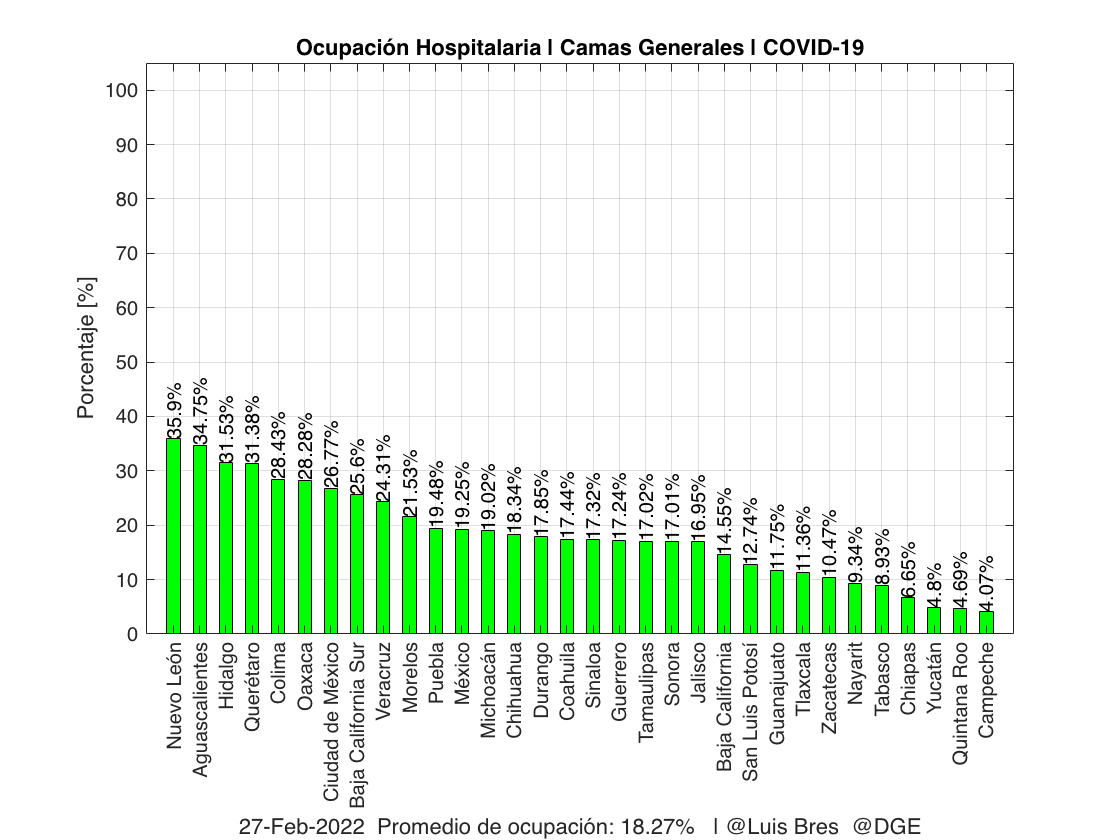

    
Mex_H_G(M_H_G,2);

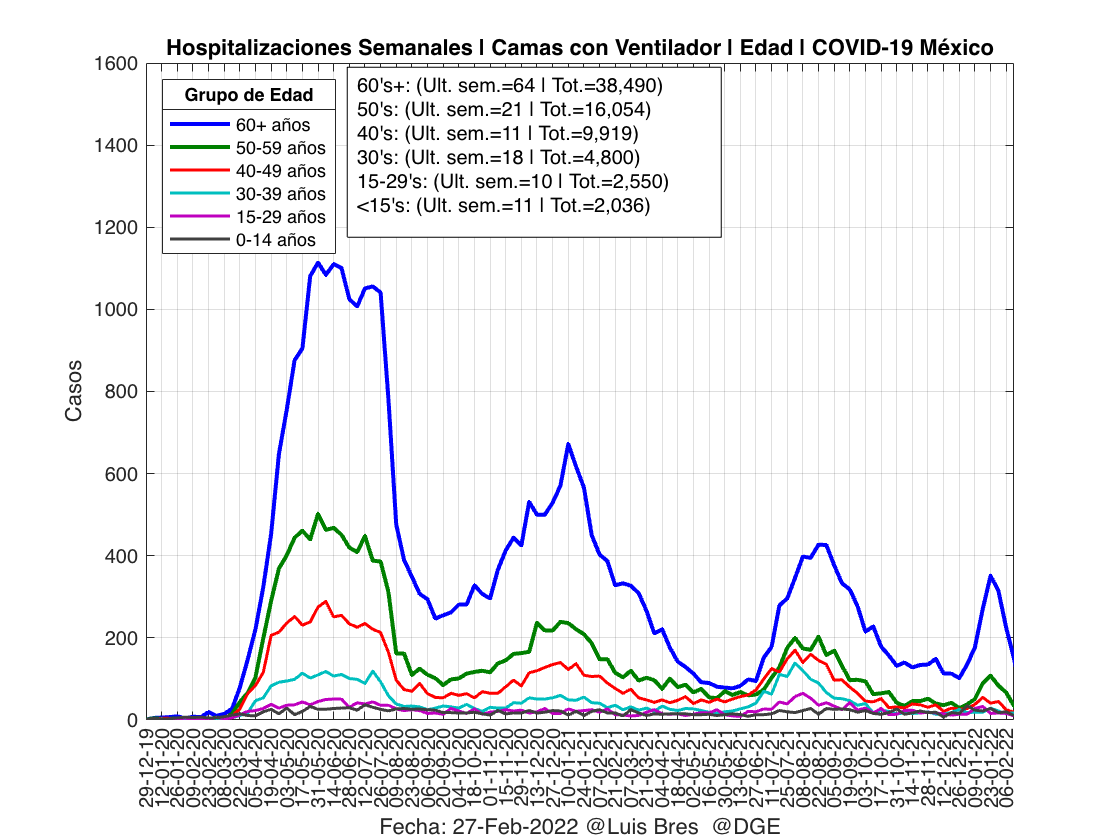

% Hosp edad Ventilador
figure
V=1;
[hv60,hvs60,phv60]=Mex_hospV_edad(Mex_dash,60,150,V);
hold on
[hv50,hvs50,phv50]=Mex_hospV_edad(Mex_dash,50,59,V);
[hv40,hvs40,phv40]=Mex_hospV_edad(Mex_dash,40,49,V);
[hv30,hvs30,phv30]=Mex_hospV_edad(Mex_dash,30,39,V);
[hv18,hvs18,phv18]=Mex_hospV_edad(Mex_dash,15,29,V);
[hv00,hvs00,phv00]=Mex_hospV_edad(Mex_dash,0,14,V);
lh=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-14 años'},'Location','NorthWest');
title(lh,'Grupo de Edad')
hold off
grid()
Hv60=CommaFormat(round(hv60(end-V),2));
Hv50=CommaFormat(round(hv50(end-V),2));
Hv40=CommaFormat(round(hv40(end-V),2));
Hv30=CommaFormat(round(hv30(end-V),2));
Hv18=CommaFormat(round(hv18(end-V),2));
Hv00=CommaFormat(round(hv00(end-V),2));

Hva60=CommaFormat(round(hvs60,2));
Hva50=CommaFormat(round(hvs50,2));
Hva40=CommaFormat(round(hvs40,2));
Hva30=CommaFormat(round(hvs30,2));
Hva18=CommaFormat(round(hvs18,2));
Hva00=CommaFormat(round(hvs00,2));
ylim([0 1600])
dimhv = [.31, .92, 0.0, 0.0];
strhv = {"60's+: (Ult. sem.="+Hv60+" | Tot.="+Hva60+")",...
       "50's: (Ult. sem.="+Hv50+" | Tot.="+Hva50+")",...
       "40's: (Ult. sem.="+Hv40+" | Tot.="+Hva40+")",...
       "30's: (Ult. sem.="+Hv30+" | Tot.="+Hva30+")",...
       "15-29's: (Ult. sem.="+Hv18+" | Tot.="+Hva18+")",...
       "<15's: (Ult. sem.="+Hv00+" | Tot.="+Hva00+")"
       };
textboxhv=annotation('textbox',dimhv,'String',strhv,'FitBoxToText','on');
set(textboxhv,'BackgroundColor','white')

strhv1 = ["60's+: (Ult. sem.="+Hv60+" | Tot.="+Hva60+")";...
       "50's: (Ult. sem.="+Hv50+" | Tot.="+Hva50+")";...
       "40's: (Ult. sem.="+Hv40+" | Tot.="+Hva40+")";...
       "30's: (Ult. sem.="+Hv30+" | Tot.="+Hva30+")";...
       "18's: (Ult. sem.="+Hv18+" | Tot.="+Hva18+")";...
       "<18's: (Ult. sem.="+Hv00+" | Tot.="+Hva00+")";
       ];
disp(strhv1)

    "60's+: (Ult. sem.=121 | Tot.=34,775)"
    "50's: (Ult. sem.=26 | Tot.=14,825)"
    "40's: (Ult. sem.=18 | Tot.=9,137)"
    "30's: (Ult. sem.=8 | Tot.=4,370)"
    "18's: (Ult. sem.=9 | Tot.=1,966)"
    "<18's: (Ult. sem.=24 | Tot.=1,852)"



M_H_V=readtable('Sistema de Información de la Red IRAG (1).xlsx');

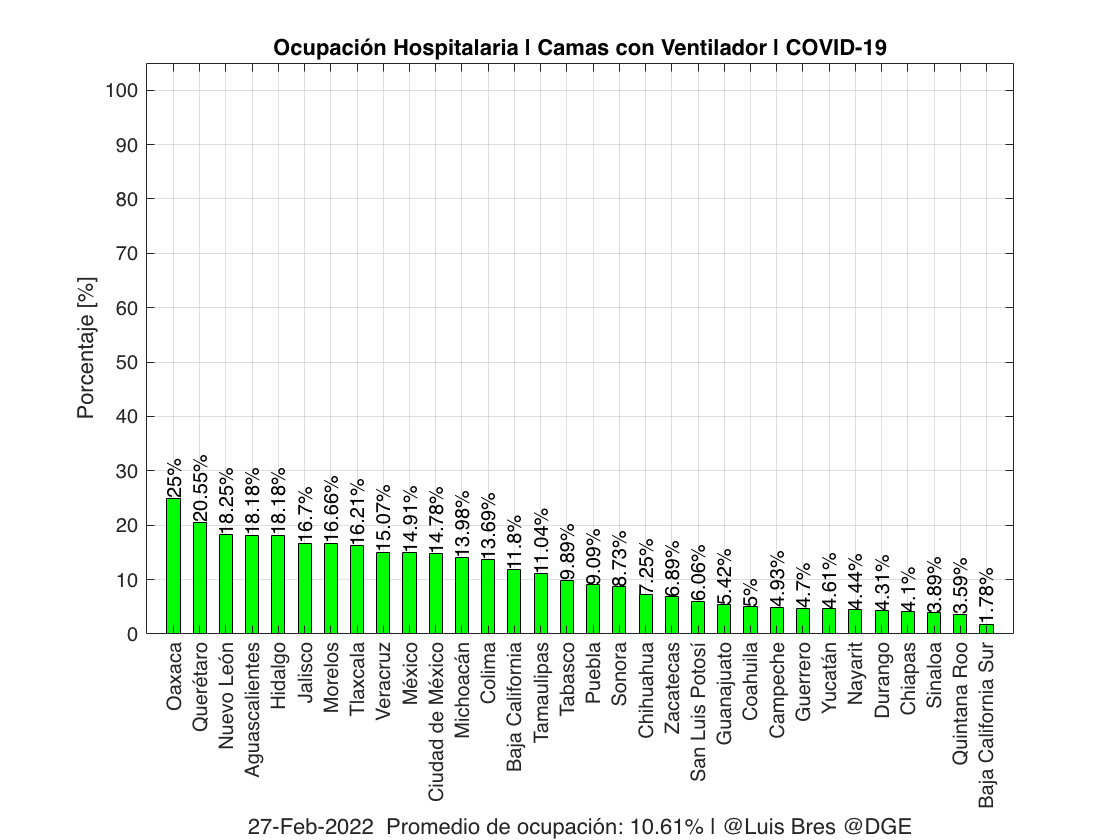

Mex_H_V(M_H_V,2);

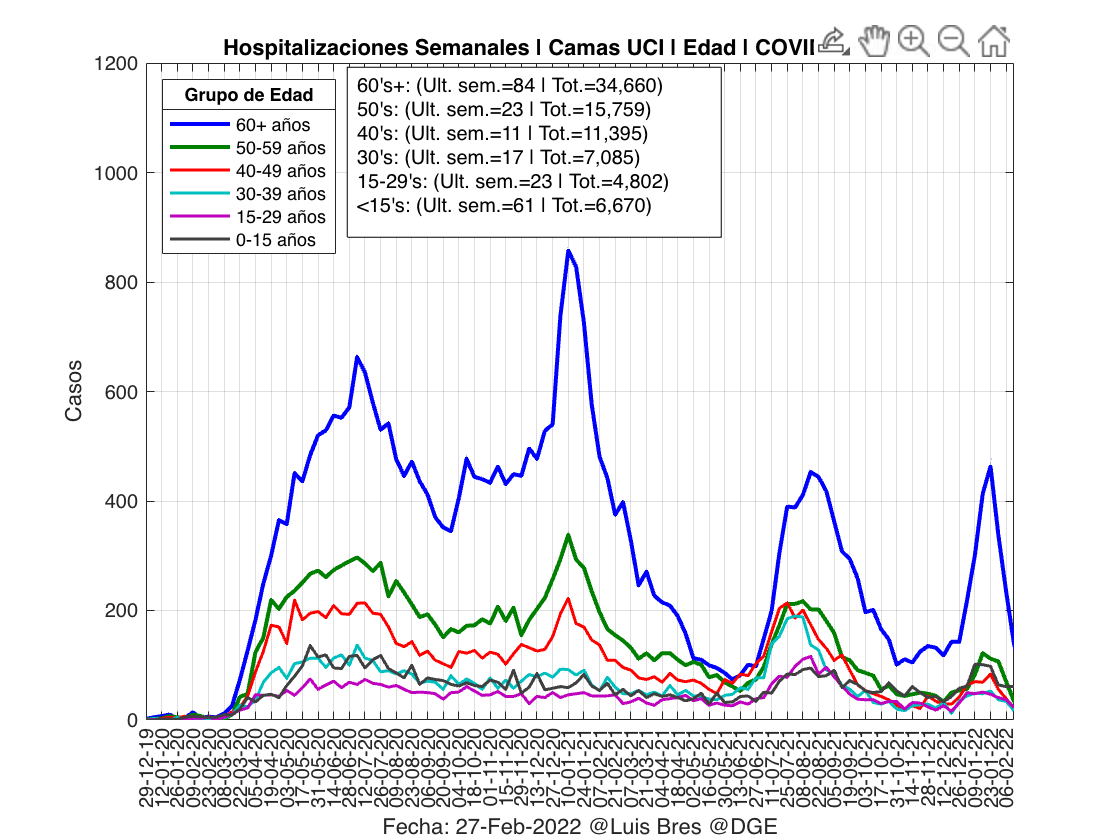

% Hosp edad UCI
figure
U=1;
[hu60,hus60,phu60]=Mex_hospUCI_edad(Mex_dash,60,150,U);
hold on
[hu50,hus50,phu50]=Mex_hospUCI_edad(Mex_dash,50,59,U);
[hu40,hus40,phu40]=Mex_hospUCI_edad(Mex_dash,40,49,U);
[hu30,hus30,phu30]=Mex_hospUCI_edad(Mex_dash,30,39,U);
[hu18,hus18,phu18]=Mex_hospUCI_edad(Mex_dash,15,29,U);
[hu00,hus00,phu00]=Mex_hospUCI_edad(Mex_dash,0,14,U);
lh=legend({'60+ años','50-59 años','40-49 años','30-39 años','15-29 años','0-15 años'},'Location','NorthWest');
title(lh,'Grupo de Edad')
hold off
grid()
Hu60=CommaFormat(round(hu60(end-U),2));
Hu50=CommaFormat(round(hu50(end-U),2));
Hu40=CommaFormat(round(hu40(end-U),2));
Hu30=CommaFormat(round(hu30(end-U),2));
Hu18=CommaFormat(round(hu18(end-U),2));
Hu00=CommaFormat(round(hu00(end-U),2));

Hua60=CommaFormat(round(hus60,2));
Hua50=CommaFormat(round(hus50,2));
Hua40=CommaFormat(round(hus40,2));
Hua30=CommaFormat(round(hus30,2));
Hua18=CommaFormat(round(hus18,2));
Hua00=CommaFormat(round(hus00,2));
ylim([0 1200])
dimhu = [.31, .92, 0.0, 0.0];
strhu = {"60's+: (Ult. sem.="+Hu60+" | Tot.="+Hua60+")",...
       "50's: (Ult. sem.="+Hu50+" | Tot.="+Hua50+")",...
       "40's: (Ult. sem.="+Hu40+" | Tot.="+Hua40+")",...
       "30's: (Ult. sem.="+Hu30+" | Tot.="+Hua30+")",...
       "15-29's: (Ult. sem.="+Hu18+" | Tot.="+Hua18+")",...
       "<15's: (Ult. sem.="+Hu00+" | Tot.="+Hua00+")"
       };
textboxhu=annotation('textbox',dimhu,'String',strhu,'FitBoxToText','on');
set(textboxhu,'BackgroundColor','white')

strhu1 = ["60's+: (Ult. sem.="+Hu60+" | Tot.="+Hua60+")";...
       "50's: (Ult. sem.="+Hu50+" | Tot.="+Hua50+")";...
       "40's: (Ult. sem.="+Hu40+" | Tot.="+Hua40+")";...
       "30's: (Ult. sem.="+Hu30+" | Tot.="+Hua30+")";...
       "18's: (Ult. sem.="+Hu18+" | Tot.="+Hua18+")";...
       "<18's: (Ult. sem.="+Hu00+" | Tot.="+Hua00+")";
       ];
disp(strhu1)

    "60's+: (Ult. sem.=107 | Tot.=30,170)"
    "50's: (Ult. sem.=50 | Tot.=14,243)"
    "40's: (Ult. sem.=29 | Tot.=10,403)"
    "30's: (Ult. sem.=43 | Tot.=6,392)"
    "18's: (Ult. sem.=30 | Tot.=3,631)"
    "<18's: (Ult. sem.=44 | Tot.=5,912)"



M_H_U=readtable('Sistema de Información de la Red IRAG (2).xlsx');

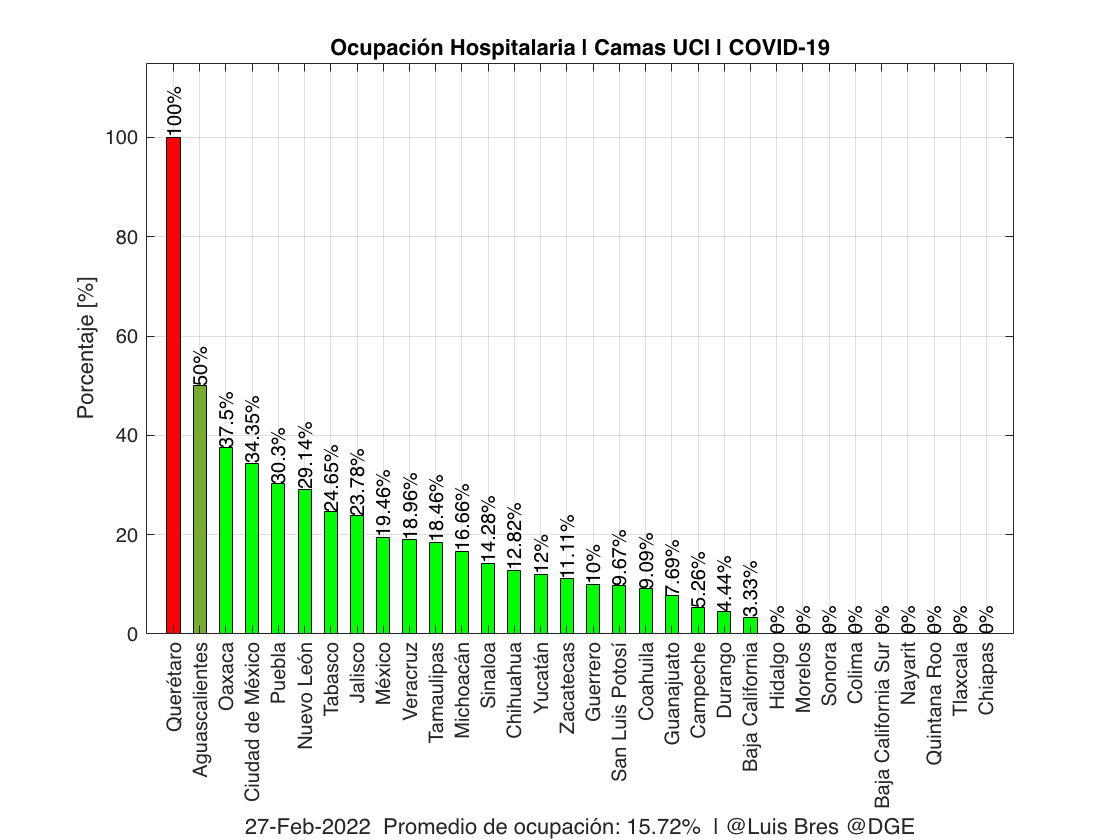

Mex_H_U(M_H_U,2);

% figure
% subplot(2,1,1)
% Tam_casos_dia(Mex_dash);
% 
% subplot(2,1,2)
% Tam_muertes_dia(Mex_dash);

% figure
% subplot(2,1,1)
% Tam_hosp_dia(Mex_dash);
% 
% subplot(2,1,2)
% Hosp_porc_Tam();

% figure
% subplot(2,1,1)
% Mat_casos_dia(Mex_dash);
% 
% subplot(2,1,2)
% Mat_muertes_dia(Mex_dash);

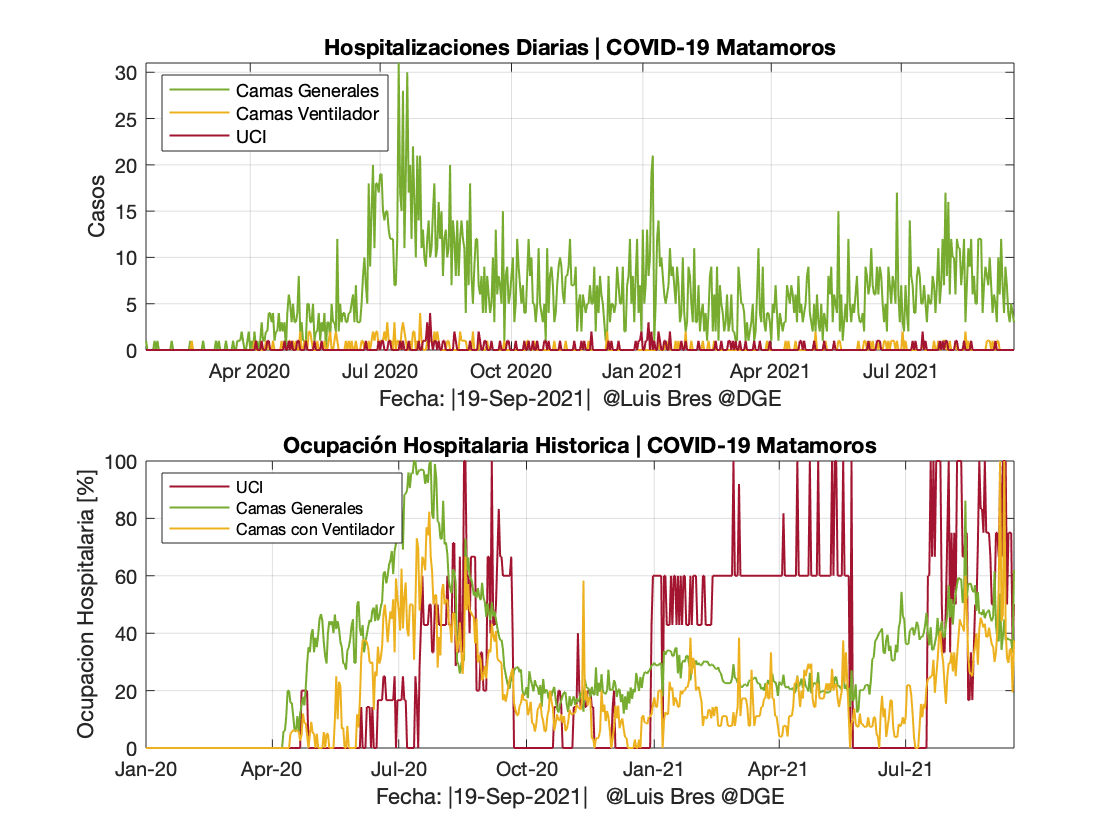

% figure
% subplot(2,1,1)
% Mat_hosp_dia(Mex_dash);
% 
% subplot(2,1,2)
% Hosp_porc_Mat();